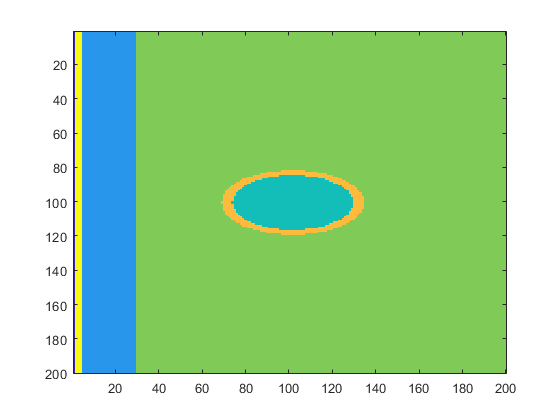

ymin = - model.G.Ly / 2 ;
ymax = + model.G.Ly / 2 ;
length_y = model.G.ny ;
% linear: y = m x + b
% 
x = model.G.x ; % values used in the model
y = model.G.y ; % 
z = model.G.z ; % 
ycm = 0.2 ;
[~,yi] = min(abs(y-ycm)) ;
A = model.G.M_raw(:,yi,:) ;
A = reshape(A,200,200);
figure, imagesc(A)

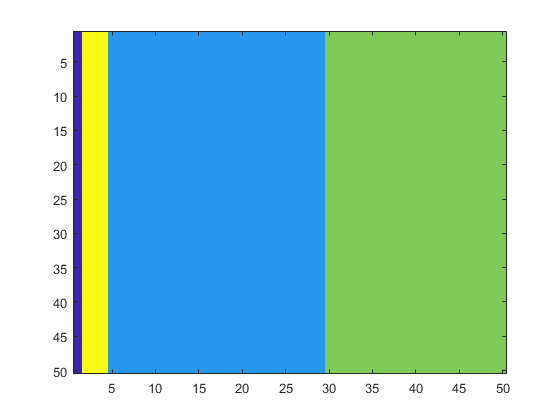

index_x = 1:50 ;
% index_y = 1:50 ;
index_z = 1:50 ;
A = model.G.M_raw(index_x,50,index_z) ;
A = reshape(A,length(index_x),length(index_z));
figure, imagesc(A)

MCorFMC = model.MC ;
mua_vec = [MCorFMC.mediaProperties.mua];
test2 = mua_vec(MCorFMC.M).*MCorFMC.NFR ;

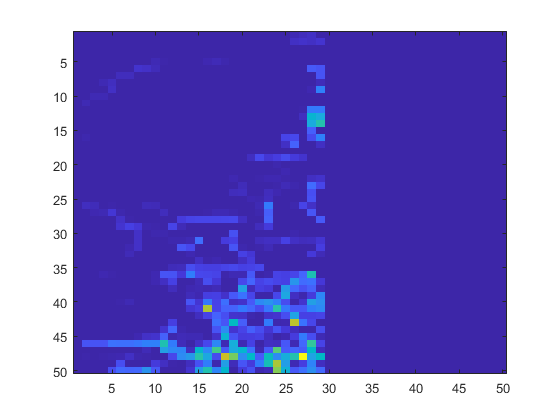

index_x = 1:50 ;
% index_y = 1:50 ;
index_z = 1:50 ;
A = test2(index_x,50,index_z) ;
A = reshape(A,length(index_x),length(index_z));
figure, imagesc(A)

% Collector position [cm]
xcm = model.MC.LC.x ;
ycm = model.MC.LC.y ;
zcm = model.MC.LC.z ;
% indexes collector [pix]
[~,xi] = min(abs(x-xcm)) ;

xi = 26

[~,yi] = min(abs(y-ycm)) ;
[~,zi] = min(abs(z-zcm)) ;

% size collector 3.5mm side square?
side = 2.1 /10 ; % approx. 2.1 based on Figure 4 2020-Bonya

dx = model.G.dx ; % values used in the model
dy = model.G.dy ; % 
dz = model.G.dz ; % 

sdx = side / dx ; % pixels number for x dimension

sdx = 30.0000

sdy = side / dy ; % pixels number for y dimension

sdy = 15.0000

sdz = side / dz ; % pixels number for z dimension

sdz = 52.5000


% select cube
index_x = xi - floor( sdx / 2 ) : xi + floor( sdx / 2 ) ;

index_x =     11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41


index_y = yi - floor( sdy / 2 ) : yi + floor( sdy / 2 ) ;
index_z = zi : zi + floor( sdz / 2 ) ;
A = test2(index_x,index_z,index_z) ;